# **磁偶极子磁力线绘制**

**        任何载流细导线回路都可看成一个磁偶极子。此程序中，磁场分布采用一个半径为a、载流为I的电流环在周围产生的磁场，即磁偶极子的磁场。该磁场在球坐标系下有如下分布：**


$$\begin{array}{l}
B_r =\frac{\mu_0 \;I\;a\;}{\pi }\frac{\;a\;\cos \theta }{\sqrt{r^2 +a^2 +2a\;r\;\sin \theta }}\left\lbrack \frac{E\left(k\right)}{r^2 +a^2 -2a\;r\;\sin \theta }\right\rbrack \\
B_{\theta } =\frac{\mu_0 \;I\;a\;}{\pi }\frac{1}{\sqrt{r^2 +a^2 +2a\;r\;\sin \theta }}\frac{1}{2a\;\sin \theta }\left\lbrack \frac{r^2 +a^2 -2a^2 {\sin \theta }^2 }{r^2 +a^2 -2a\;r\;\sin \theta }E\left(k\right)-K\left(k\right)\right\rbrack 
\end{array}$$


**        其中，**$k^2 =\frac{4a\;r\;\sin \theta }{r^2 +a^2 +2a\;r\;\sin \theta }$**,**$E\left(k\right)$**与**$K\left(k\right)$**是MATLAB下内置的椭圆积分函数。**

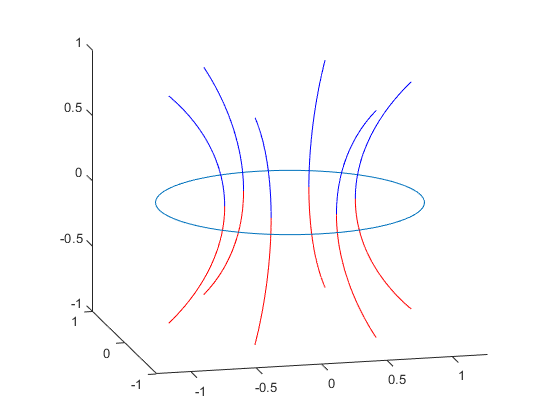

clc
clear
I=1000000;                    %自定义电流大小，默认值1e6
mu0=4*pi*1e-7;                       	%真空中的磁导率
C=mu0/pi*I;                           	%归并常数
a=1;                    %自定义线圈半径，默认值1
aplha=0:pi/40:2*pi;                     %以下语句用于绘制载流圆环，设置角度
x0=a*cos(aplha);                       	%计算x坐标
y0=a*sin(aplha);                        %计算y坐标
plot(x0,y0,'-');                        %绘制圆环
hold on;
r(1)=0.5*a;           %起始点，球坐标系下：(0.5a,pi/2,0)，即xoz平面上的点
t(1)=pi/2;            %起始点，球坐标系下：(0.5a,pi/2,0)，即xoz平面上的点
k = sqrt(4*a.*r(1)*sin(t(1))./(r(1).^2+a.^2+2.*a.*r(1)*sin(t(1))));     %计算k
K = ellipticK(k.^2);                   	%椭圆积分
E = ellipticE(k.^2);                 	%椭圆积分
Br(1) = C*a.*(a.*cos(t(1)))./(sqrt(r(1).^2+a.^2+2*a.*r(1).*sin(t(1)))).*(E./(r(1).^2+a.^2-2*a.*r(1).*sin(t(1))));
Bt(1) = C*a.*(1./(sqrt(r(1).^2+a.^2+2*a.*r(1).*sin(t(1)))).*(1./(2*a.*sin(t(1)))).*((a.^2+r(1).^2-2.*a.^2.*sin(t(1)).^2)./(r(1).^2+a.^2-2*a.*r(1).*sin(t(1))).*E-K));
B(1) = sqrt(Br(1).^2+Bt(1).^2);            	%计算磁场B的大小
eBr(1) = Br(1)/B(1);                     	%计算单位矢量，r分量
eBt(1) = Bt(1)/B(1);                     	%计算单位矢量，theta分量
l=a/1000;                              	    %力线长度增量，即deltaL
for i=2:1:1000                          	%逐点绘制力线
    r(i)=r(i-1)+l*eBr(i-1);                	%下一点的r值
    t(i)=t(i-1)+l*eBt(i-1)/r(i-1);          %下一点的theta值
    k = sqrt(4*a.*r(i)*sin(t(i))./(r(i).^2+a.^2+2.*a.*r(i)*sin(t(i))));   %计算新点的磁场
    K = ellipticK(k.^2);
    E = ellipticE(k.^2);
    Br(i) = C*a.*(a.*cos(t(i)))./(sqrt(r(i).^2+a.^2+2*a.*r(i).*sin(t(i)))).*(E./(r(i).^2+a.^2-2*a.*r(i).*sin(t(i))));
    Bt(i) = C*a.*(1./(sqrt(r(i).^2+a.^2+2*a.*r(i).*sin(t(i)))).*(1./(2*a.*sin(t(i)))).*((a.^2+r(i).^2-2.*a.^2.*sin(t(i)).^2)./(r(i).^2+a.^2-2*a.*r(i).*sin(t(i))).*E-K));
    B(i) = sqrt(Br(i).^2+Bt(i).^2);
    eBr(i) = Br(i)/B(i);                    	%计算单位矢量
    eBt(i) = Bt(i)/B(i);                    	%计算单位矢量，并重复下一个点
end
th0 = 0:pi/3:2*pi;                        	%以下代码，用于将一条磁力线，绕z轴旋转
r = r';                                 	%力线上各点的r值
t = t';                                  	%力线上各点的theta值
x=r.*sin(t);   z=r.*cos(t);                 %转换为直角坐标
ZZ(:,1:7) = z.*ones(1,7);              	    %旋转之后，各条力线的z坐标
XX(:,1:7) = x.*cos(th0(1:7));               %旋转之后，各条力线的x坐标
YY(:,1:7) = x.*sin(th0(1:7));               %旋转之后，各条力线的y坐标
plot3(XX,YY,ZZ,'b')                      	%绘制上半平面力线
plot3(XX,YY,-ZZ,'r')                     	%绘制下半平面力线
axis equal;                             	%等比例显示
box off;                                	%关闭以坐标轴为长宽高的长方体盒子
view([-13.69 13.84]);
hold off;
set(gcf,'Visible','on');   	    %强制图片弹出显示